# Lab 5: Cross-Device OFDM Transmission

## [Part 2]

clear;
N = 64;
Ncp = 16;
fc = 915*1e6;
fs = 1e6;

pilot_bins = [-21 -7 7 21];
used_bins  = setdiff([-26:-1 1:26], pilot_bins);
idx = @(k) k + N/2 + 1;
N_samp = 100;
pilot_bits = randi([0 1], numel(pilot_bins), 1);
pilot = pskmod(pilot_bits, 2);

### training symbols generation

sts_bins = [-24 -20 -16 -12 -8 -4 4 8 12 16 20 24];
sts_signs = [ 1 -1  1 -1 -1  1 -1 -1  1  1  1  1];  
    
% Map to FFT bins
X_sts = zeros(N,1);
for i = 1:numel(sts_bins)
    X_sts(idx(sts_bins(i))) = sts_signs(i) * (1+1j);
end
X_sts = X_sts * sqrt(13/6);
    
x_sts_64 = ifft(ifftshift(X_sts), N);
x_sts_16 = x_sts_64(1:Ncp);
x_sts = repmat(x_sts_16, 10, 1);

lts_bins = [-26:-1 1:26];
lts_signs = [ ...
1,  1, -1, -1,  1,  1, -1,  1, -1,  1,  1,  1,  1,  1,  1, -1, -1,  1,  1, -1,  1, -1,  1,  1,  1,  1, ...
1, -1, -1,  1,  1, -1,  1, -1,  1, -1, -1, -1, -1, -1,  1,  1, -1, -1,  1, -1,  1, -1,  1,  1,  1,  1];
    
X_lts = zeros(N,1);
for i = 1:numel(lts_bins)
    X_lts(idx(lts_bins(i))) = lts_signs(i);
end
    
x_lts = ifft(ifftshift(X_lts), N);

## (1)

data_bits = randi([0 1], numel(used_bins)*log2(4), N_samp);
x_tx = OFDM(data_bits, N_samp, pilot, idx(pilot_bins), idx(used_bins), N, Ncp, 4);
[x_tx_TS, lts_normalization_factor] = add_TS(x_tx, x_sts, x_lts);
x_tx_ext = [zeros(100,1); x_tx_TS; zeros(100,1)];

[x_rx1, x_rx2] = USRP_channel_multi(x_tx_ext, x_lts, x_sts, 1);

Detected strong frame at ii=2, P=0.0001 > THR=0.0001


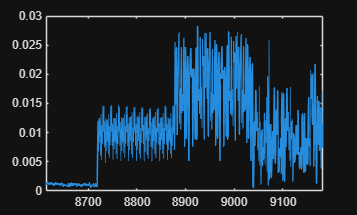


figure;
t_axis = (0:numel(x_tx_TS)-1)/fs;
plot(1:length(x_rx1), abs(x_rx1), 'LineWidth', 1.2);

figure;
plot(1:length(x_rx2), abs(x_rx2), 'LineWidth', 1.2);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
legend('RX1', "RX2");

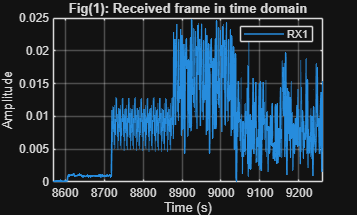

title('Fig(1): Received frame in time domain');

functions:

function [radio_Tx, radio_Rx] = USRP_init_multi(rx_length, fs)
% USRP init for N200/N210/USRP2 with 10 MS/s host rate
    platform  = "N200/N210/USRP2";
    address   = '192.168.10.2';
    fc = 915*1e6;     % center frequency
    txGain_dB = 5;         % tune as needed (avoid clipping)
    rxGain_dB = 20;
    interfactor = round(100/fs);
    decimfactor = round(20/fs);

    radio_Tx = comm.SDRuTransmitter( ...
        'Platform',          platform, ...
        'IPAddress',         address, ...
        'CenterFrequency',   fc, ...
        'Gain',              txGain_dB, ...
        'MasterClockRate',   100e6, ...
        'InterpolationFactor', interfactor);

    radio_Rx = comm.SDRuReceiver( ...
        'Platform',          "B210", ...
        'SerialNum',         "319BF05", ...
        'CenterFrequency',   fc, ...
        'SamplesPerFrame',   rx_length, ...
        'ChannelMapping',    [1,2], ...
        'Gain',              [20 5], ...
        'MasterClockRate',   20e6, ...
        'DecimationFactor',  decimfactor, ...
        'OutputDataType',    'double');
end

function x_cp = OFDM(data_bits, N_samp, pilot, pilot_bins, used_bins, FFT_size, cp_size, qam)
    data_symb = qammod(data_bits, qam, 'gray', InputType='bit', UnitAveragePower=true);
    
    xcp_all = complex(zeros(FFT_size+cp_size, N_samp));
    
    for n = 1:N_samp
        % ----- 1) Build frequency-domain X for one OFDM symbol -----
        X = zeros(FFT_size,1);
    
        % pilots (BPSK ±1)
        X(pilot_bins) = pilot;
    
        % data (take this symbol's mapped constellation)
        X(used_bins) = data_symb(:, n);
    
        % ----- 2) IFFT -> time domain -----
        x = ifft(ifftshift(X));                % 64 samples
    
        % ----- 3) Add cyclic prefix -----
        xcp_all(:, n) = [x(end-cp_size+1:end); x];
    end
    x_cp = xcp_all(:);
end

function [x_ts, alpha_lts] = add_TS(x_tx, x_sts, x_lts)

    CP_LTS = 32;

    % --- Compute average powers ---
    P_tx  = mean(abs(x_tx).^2);
    P_lts = mean(abs(x_lts).^2);

    % alpha_lts = sqrt(P_tx / max(P_lts, eps));
    alpha_lts = max(abs(x_tx)) / max(abs(x_lts));

    x_lts_norm = alpha_lts * x_lts;

    x_lts_field = [x_lts_norm(end-CP_LTS+1:end); x_lts_norm; x_lts_norm];
    x_ts = [x_sts; x_lts_field; x_tx];
end

function H_LTS = channel_est(frame_LTS, x_lts, normalization_factor)
    X_LTS = fftshift(fft(x_lts));
    frame_lts1 = frame_LTS(32+1:32+64);
    frame_lts2 = frame_LTS(end-64+1:end);
    Y_LTS1 = fftshift(fft(frame_lts1));
    Y_LTS2 = fftshift(fft(frame_lts2));
    H_LTS = (Y_LTS1+Y_LTS2)/(2*normalization_factor) .* X_LTS;
end

function BER = ber_cal(x, y)
    BER = mean(x ~= y);
end

function x_rx = USRP_channel_new(x_tx_CFO, x_lts, x_sts, fs)
    Fs = 1e6; % host-side rate (matches Interp/Decim=10 for 100 MHz) 
    Ns_frame = numel(x_tx_CFO); 
    % ---- Build one TX packet per iteration: frame + guard zeros (fixed length) ---- 
    guard_len = 0; % 80 us of silence @ 10 MS/s (tune 400–2000 as needed) 
    tx_one = [x_tx_CFO(:); zeros(guard_len,1)]; % complex column 
    Ltx = numel(tx_one); % ---- Backoff to avoid clipping at DAC ---- % 
    
    rx_length = 2.0*Ltx; 
    [radio_Tx, radio_Rx] = USRP_init(rx_length, fs); 
    l = rx_length; 
    n = 2000;
    % buffer = complex(zeros(n+30,rx_length)) ;
    THR_POW = 1e-4;
    found = false;
    det_idx = NaN;
    max_scan = n+50;
    success = false;
    % Transmit and receive for 50 frames 
    while ~success
        buffer = complex(zeros(n+30,rx_length)) ;

        for k = 1:3
            step(radio_Rx);
        end
        for ii = 1 : max_scan 
            tunderrun = radio_Tx(tx_one); 
            [rcvdSignal, ~, toverflow] = step(radio_Rx); % buffer(ii,:) = real(rcvdSignal.' ); 
            buffer(ii,:) = rcvdSignal.' ; 
            received_power = mean(abs(rcvdSignal).^2);
            if ~found && received_power>THR_POW
                found = true;
                det_idx = ii;
                fprintf('Detected strong frame at ii=%d, P=%.3g > THR=%.3g\n', ii, received_power, THR_POW);
                break
            end
            if found
                break
            end
        end
        
        
        if found
            for jj = 1:30
                [rcvdSignal, ~, toverflow] = step(radio_Rx); %#ok<ASGLU>
                buffer(det_idx+jj,:) = rcvdSignal.';
            end
            last_idx = det_idx + 30;
        else
            % If not found, still capture some extra for inspection
            fprintf('No strong frame detected (THR=%.3g). Capturing 30 extra frames anyway.\n', THR_POW);
            for jj = 1:30
                [rcvdSignal, ~, toverflow] = step(radio_Rx); %#ok<ASGLU>
                buffer(max_scan+jj,:) = rcvdSignal.';
            end
            last_idx = max_scan + 30;
        end
        
        
        % ---- Quick health checks ---- 
        rx_peaks = max(abs(buffer(1:n,:)),[],2); 
        fprintf('TX peak after backoff: %.3f | median RX peak: %.3f\n', max(abs(tx_one)), median(rx_peaks));
        % fprintf('TX peak after backoff: %.3f | median RX peak: %.3f\n', max(abs(tx_one)), median(rx_peaks));
        
        % ---- Pick one received frame and plot with region markers (no correlation yet) ----
        buffer_squeezed = reshape(buffer.', 1, []).';
        Ncp_LTS = 32;        % LTS CP length (samples)
        ST_len = 16;        % short symbol length
        sts_len = 10*ST_len; % 10 repeats of 16
        LT_len = 64;        % one LTS body
        N = 64;
        extracted_piece = buffer_squeezed;
        x_received = extracted_piece(:).';         % ensure row vector
        
        % x_received = frame;
        
        % ---- LTS matched filter (time-reversed, conjugated) ----
        hL = conj(fliplr(x_lts));           % MF kernel
        yL_full = conv(x_received, hL, 'full');
        yL = yL_full(1:length(x_received));   % align length
        
        % ---- Two-peak comb: pick two adjacent LTS (LTS1 & LTS2) ----
        combL = zeros(1, 2*N);             % length = 128
        combL(1) = 1;
        combL(N+1) = 1;                          % second peak N samples later
        
        % Convolve comb with |yL| to score aligned double-LTS patterns
        zL_full = conv(yL, combL, 'full');
        zL= zL_full(numel(combL):end);        % align to x_received
        % if max(abs(zL)) > 0.02
        %     success = true;
        % end
        % fprintf("Not successful, retry...");
        success = true;
        fprintf("max zl = %.4f", max(abs(zL)));
    end
    release(radio_Tx) 
    release(radio_Rx) 
    % ---- Peak detection & indices ----
    [~, zL_max_index] = max(abs(zL));   
    idx_lts1  = zL_max_index;
    idx_lts_cp = idx_lts1 - Ncp_LTS;            % CP starts 32 samples before LTS1
    idx_sts = idx_lts_cp - sts_len;          % STS region start
    idx_data = idx_lts_cp + (Ncp_LTS + 2*N);  % start of data symbols
    
    % Bound to valid range
    clip = @(x) max(1, min(x, numel(x_received)));
    idx_lts1 = clip(idx_lts1);
    idx_lts_cp = clip(idx_lts_cp);
    idx_sts = clip(idx_sts);
    idx_data = clip(idx_data);
    
    idx_frame_start = idx_sts-100;
    
    idx_sts_one_frame = idx_sts - idx_frame_start + 1;
    idx_lts1_one_frame = idx_lts1 - idx_frame_start + 1;
    idx_lts_cp_one_frame = idx_lts_cp - idx_frame_start + 1;
    idx_data_one_frame = idx_data - idx_frame_start + 1;
    
    
    % x_received_one_frame = x_received(idx_frame_start:idx_frame_start+920-1);
    
    % t_us = (0:numel(x_received_one_frame)-1)/Fs * 1e6;
    t_us = (0:length(x_received)-1)/Fs * 1e6;

    % ---- Plot: LTS MF result & 2-peak score ----
    % figure; hold on; grid on; box on;
    % plot(t_us, real(zL),     'LineWidth', 1.2, 'DisplayName','Two-peak score z_L[n]');
    % plot(t_us, real(yL), '-',        'LineWidth', 1.2, 'DisplayName','|LTS MF|');
    % plot(t_us, x_received, '--', 'LineWidth', 1.0, 'DisplayName','|x_{rx}|');
    % 
    % % Detected boundaries
    % xline(t_us(idx_sts), 'y-', 'LineWidth',1.2, 'Label','detected STS start', ...
    %     'LabelHorizontalAlignment','left','HandleVisibility','off');
    % xline(t_us(idx_lts_cp), 'm-', 'LineWidth',1.2, 'Label','detected LTS-CP start', ...
    %     'LabelHorizontalAlignment','left','HandleVisibility','off');
    % xline(t_us(idx_lts1),   'g-', 'LineWidth',1.2, 'Label','detected LTS1 start', ...
    %     'LabelHorizontalAlignment','left','HandleVisibility','off');
    % xline(t_us(idx_data),   'r-', 'LineWidth',1.2, 'Label','detected DATA start', ...
    %     'LabelHorizontalAlignment','left','HandleVisibility','off');
    % 
    % xlabel('Time (\mus)'); ylabel('Normalized metric');
    % title('LTS Matched Filter + Two-Peak Comb (detect CP, LTS1, Data start)');
    % legend('Location','northeast');
    % drawnow;

    x_received_one_frame = x_received(idx_frame_start:idx_frame_start+8520-1); % 8520 for 100 frames
    x_rx = x_received_one_frame(101: numel(x_received_one_frame)-100);
    x_rx = x_rx.';

    t_us = (0:numel(x_received_one_frame)-1)/Fs * 1e6;
    
    % figure; hold on; grid on; box on;
    % plot(t_us, real(y_win), '-',  'LineWidth', 1.0, 'DisplayName','Real');
    % plot(t_us, imag(y_win), '--', 'LineWidth', 1.0, 'DisplayName','Imag');
    
    %y_win
    
    % figure; hold on; grid on; box on;
    % plot(t_us, real(abs(zL(idx_frame_start:idx_frame_start+8520-1))),     'LineWidth', 1.2, 'DisplayName','Two-peak score z_L[n]');
    % plot(t_us, real(abs(yL(idx_frame_start:idx_frame_start+8520-1))), '-',        'LineWidth', 1.2, 'DisplayName','|LTS MF|');
    % plot(t_us, real(x_received_one_frame), '-',  'LineWidth', 1.0, 'DisplayName','Real');
    % plot(t_us, imag(x_received_one_frame), '--', 'LineWidth', 1.0, 'DisplayName','Imag');
    % Known segment lengths at 10 MS/s
    % xline(t_us(idx_sts_one_frame), 'y-', 'LineWidth',1.2, 'Label','STS start', ...
        % 'LabelHorizontalAlignment','left','HandleVisibility','off');
    % xline(t_us(idx_lts_cp_one_frame), 'm-', 'LineWidth',1.2, 'Label','LTS-CP start', ...
        % 'LabelHorizontalAlignment','left','HandleVisibility','off');
    % xline(t_us(idx_lts1_one_frame),   'g-', 'LineWidth',1.2, 'Label','LTS1 start', ...
    % xline(t_us(idx_lts1_one_frame),   'g-', 'LineWidth',1.2, 'Label','LTS1 start');
        % 'LabelHorizontalAlignment','left','HandleVisibility','off');
    % xline(t_us(idx_data_one_frame),   'r-', 'LineWidth',1.2, 'Label','DATA start', ...
        % 'LabelHorizontalAlignment','left','HandleVisibility','off');
    % xline(t_us(idx_data_one_frame+8000),   'r-', 'LineWidth',1.2, 'Label','DATA end', ...
        % 'LabelHorizontalAlignment','left','HandleVisibility','off');
    % 8000
    
    % xlabel('Time (\mus)'); ylabel('Amplitude');
    % title('Extracted RX frame @ 10 MS/s ');
    % legend('Location','northeastoutside');
    % drawnow;
end

function [x_rx1, x_rx2] = USRP_channel_multi(x_tx_CFO, x_lts, x_sts, fs)
    Fs = 1e6; % host-side rate (matches Interp/Decim=10 for 100 MHz) 
    Ns_frame = numel(x_tx_CFO); 
    % ---- Build one TX packet per iteration: frame + guard zeros (fixed length) ---- 
    guard_len = 0; % 80 us of silence @ 10 MS/s (tune 400–2000 as needed) 
    tx_one = [x_tx_CFO(:); zeros(guard_len,1)]; % complex column 
    Ltx = numel(tx_one); % ---- Backoff to avoid clipping at DAC ---- % 
    
    n = 2000;
    rx_length = 2.0*Ltx; 
    [radio_Tx, radio_Rx] = USRP_init_multi(rx_length, fs); 
    THR_POW = 1e-4;
    found = false;
    det_idx = NaN;
    max_scan = n+50;

    for ii = 1 : max_scan 
        tunderrun = radio_Tx(tx_one); 
        [rcvdSignal, ~, toverflow] = step(radio_Rx);
        received_power = sum(mean(abs(rcvdSignal).^2));
        if ~found && received_power>THR_POW
            found = true;
            det_idx = ii;
            fprintf('Detected strong frame at ii=%d, P=%.3g > THR=%.3g\n', ii, received_power, THR_POW);
            break
        end
        if found
            break
        end
    end

    x_rx1 = rcvdSignal(:, 1);
    x_rx2 = rcvdSignal(:, 2);
end


function [last_peak, status] = matched_filter(pattern, frame, L)
    mf = conj(flipud(pattern));  
    sync_s = abs(conv(frame, mf, 'same'));
    P_avg = cumsum(abs(frame).^2) ./ (1:length(frame)).' + 0.01; % This added constant avoids the peak value at the beginning when P_avg is very low
    peak_pos = (sync_s./P_avg > L);
    last_peak = find(peak_pos, 1, 'last');
    status = (sum(peak_pos) == 2);
end
